# Characterize relaxation peaks and residuals

% Ar = b
A = [];
b = [];

folder = "lattice_calibration_data/15x15x15/trial4/";
index4 = ['1';'2';'6'];
files = folder + "lattice_data_" + index4;
load("characteristic_2.mat");

% for file_i = 1:size(files,1)
%     load(files(file_i));
%     t = t_biased;
%     figure;
%     plot(t,fz,"LineWidth",1.5,"Color","red");
%     hold on;
%     plot(t,-k*z,"LineWidth",1.5,"Color","green");
%     hold off;
% end

load(files(1));

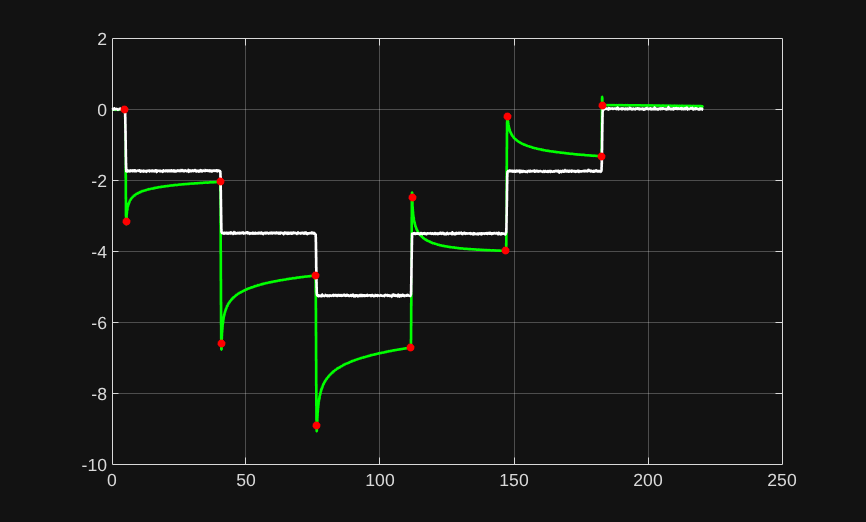

t = t_biased;
fz_fil = lowpass(fz,0.1);
z_fil = lowpass(z,0.00001,100);
v = diff(z_fil)*100;
v(end + 1) = v(end);
v_fil = lowpass(v,0.00000001,100);
dfz = diff(fz_fil)*100;
dfz(end+1) = dfz(end);
dfz_fil = lowpass(dfz,0.1);
v0 = 2e-4;
t_movs = [];
i_movs = [];
i = 1;
t_counter = 1;

length = size(v_fil,1);

while true
    if i>length
        break;
    end
    if abs(v_fil(i)) > v0
        t_movs(t_counter) = t(i-5);
        i_movs(t_counter) = i-5;
        t_counter = t_counter + 1;
        i = i+1;
        while abs(v_fil(i)) > v0
            i = i+1;
        end
        t_movs(t_counter) = t(i-1);
        i_movs(t_counter) = i-1;
        t_counter = t_counter + 1;
        i = i+1;
    else
        i = i+1;
    end
end
i_movs = i_movs';

t_movs = t_movs';
fz_movs = fz_fil(i_movs);
z_movs = z_fil(i_movs);
dfz_movs = dfz_fil(i_movs);

plot(t,fz_fil,"LineWidth",1.5,"Color","green");
hold on;
plot(t,-k*z,"LineWidth",1.5,"Color","white");
scatter(t_movs,fz_movs,20,"red","filled");
grid on;
hold off;

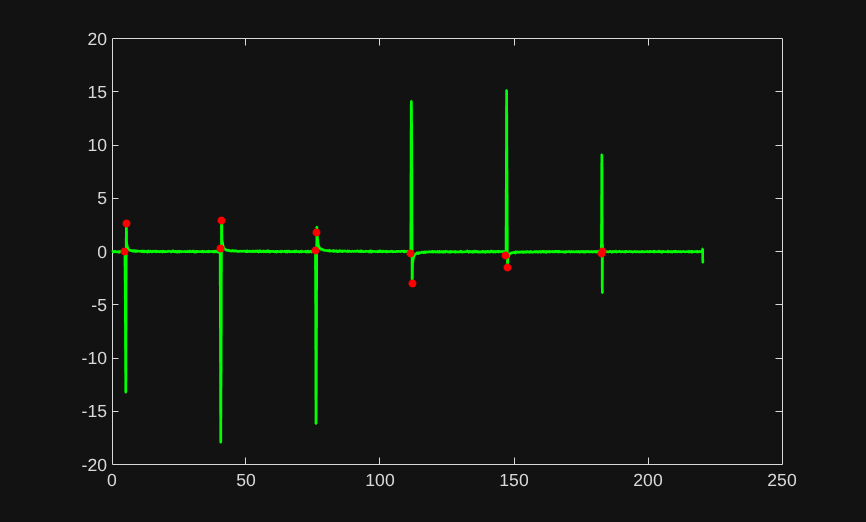


plot(t,dfz_fil,"LineWidth",1.5,"Color","green");
hold on;
scatter(t_movs,dfz_movs,20,"red","filled");
hold off;

% t_movs
% i_movs
% fz_movs
% z_movs
% assume residuals  has been achieved

% get the equations first
for i=1:3
    b = [b;[-z_movs(2*i)*k  - fz_movs(i*2)]];
    b = [b;[-k*z_movs(2*i) - fz_movs(2*i + 1)]];
    A = [A;[z_movs(2*i) z_movs(2*i)]];
    A = [A;[0 z_movs(2*i)]];
end

% linear regression least squares now
r = inv(A'*A)*(A'*b);

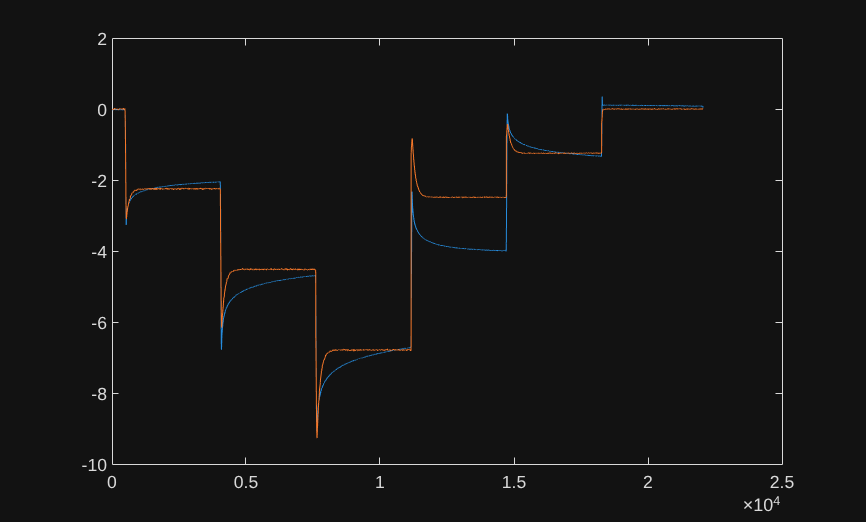

t_inv = 0.1;
fz_est = estimate_lattice_force(z_fil,t,t_inv,k,r(1),r(2),kr);